% Test of the influence of Hamming Weight of operand
%8 bits

rng shuffle

numberOfRandomNumbers= 1000000;
%Obtain random 8 bits numbers for A
vectorA = randi([0 2^16-1], 1, numberOfRandomNumbers);
vectorB = 0 : 2^16-1;
sumHammingWeights = zeros(2,17);
for i = 1 : length(vectorB)
    hwB = hammingWeight(vectorB(i));
    sumHammingWeights(1,hwB+1) = sumHammingWeights(1,hwB+1) + sum(hammingWeight(vectorA*vectorB(i)));
    sumHammingWeights(2,hwB+1) = sumHammingWeights(2,hwB+1) + numberOfRandomNumbers;
end

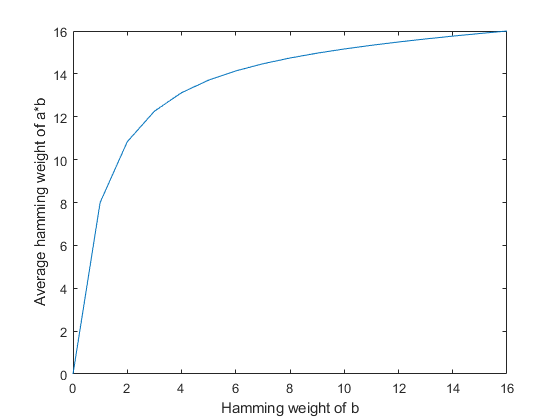

averageHammingWeights = sumHammingWeights(1,:) ./ sumHammingWeights(2,:);
plot([0:16],averageHammingWeights)
xlabel("Hamming weight of b")
ylabel("Average hamming weight of a*b")

corrcoef(averageHammingWeights,[0:16])

ans =     1.0000    0.7610
    0.7610    1.0000
